%test galactic

format short % long for 15 sig figs, change to short for 4 sig figs

SegmentModulesWeight = 6.3940

TopStress = 4.7328e+05

WidthStress = 5.6794e+06

DepthStress = 2.1130e+06

SafetyFactorCasing = 46.1320

MaxTensileForFastener = 1.6649e+04

SafetyFactorBoltTension = 26.5707

SafetyFactorVoltShear = 10.8390

maxTearoutForce = 1.3310e+04

MinFlangeBondArea = 1.6524e-04

DepthRestrictingBondArea = 5.0800e-04

SideBondArea = 2.5400e-04

bondMaxForce = 1.1558e+04

vmax = 0.0060

MomentOfInertiaSideWalls = 1.3645e-06

MomentOfInertiaBottom = 8.0950e-07

MomentOfInertiaLid = 1.3004e-06

ixx = 3.4744e-06

RadiusOfGyration = 0.0541

SlendernessRatioCasing = 7.7050

SlendernessRatioForHalfStrength = 35.3085

MaxForceJohnson = 3.0338e+05

heatFluxPerC = 7.0658

## SES

#### UTS*Area load cases 

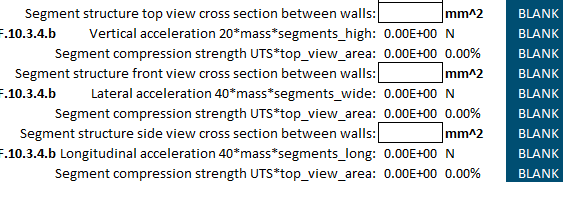

#### Module Volume

[https://enepaq.com/wp-content/uploads/2023/09/VTC6-Sony-Murata-Li-ion-Battery-Module-With-Temperature-Sensor-Datasheet-Tesla-Battery-Sponsorship-Formula-SAE-Electric-Formula-Student-Battery-Pack.pdf](https://enepaq.com/wp-content/uploads/2023/09/VTC6-Sony-Murata-Li-ion-Battery-Module-With-Temperature-Sensor-Datasheet-Tesla-Battery-Sponsorship-Formula-SAE-Electric-Formula-Student-Battery-Pack.pdf) 

EneModWidth = 20.13418951/1000%(m)
EneSegHeight =  105.6/1000%(m)
EneModDepth = 69.5/1000%(m)
ModuleWeight = 278/1000%kg

### Segment Dimensions

SegmentCasingHeight = EneSegHeight%m
EneSegmentDepth = 6*EneModDepth%num moduleSs*moduleDepth*mmtoinches + flange added length - hole locatoin
EneSegmentWidth = EneModWidth * 4
garoliteThickness = (1/16)*25.4/1000%m
SegmentModulesWeight = ModuleWeight*23%kg


### Segment Cross Sectional Areas

TopCrossSecArea = EneSegmentDepth*garoliteThickness*2;
WidthCrossSecArea = EneSegmentDepth*garoliteThickness*2;
DepthCrossSecArea = EneSegmentWidth*garoliteThickness*2 + EneSegHeight*GaroliteThickness*2;
airHoleDia = 8/1000;%m

### Tab Gluing Strength

Pload = 9.8*20*SegmentModulesWeight
insetlength = 26.75/1000%m
bolttosegmentlength = 14/1000%m
L1 = 14/1000%m
L2 = 40.75/1000%m
P1 = -(Pload*L1)/(L2-L1)
P2 = (Pload*L2)/(L2-L1)
Mc = Pload*L2 - P1*(L2-L1)

### Garolite Properties

psiTopPascal = 6894.76;
garoliteStrength = 38000*psiTopPascal;%262,000,000pa
garoliteFlexuralModulus = 2400* 1000 * psiTopPascal

### Vertical Minimum Column Properties

vmincolumnlength = EneSegmentWidth*1000%mm
vmincolumnarea = (garoliteThickness*EneSegHeight - 5*airHoleDia*garoliteThickness)*1000^2%mm^2
vmincolumnMOI = ((garoliteThickness^3*(EneSegmentWidth-5*airHoleDia))/12)*1000^4%mm^4
vPcrEuler = (pi^2*garoliteFlexuralModulus*vmincolumnMOI)/vmincolumnlength^2
v

### Lateral Minimum Column Properties

lmincolumnlength = EneSegmentDepth*1000%mm
lmincolumnarea = (garoliteThickness*(EneSegmentWidth+2*garoliteThickness))*1000^2%mm^2
lmincolumnMOI = ((garoliteThickness^3*(EneSegmentWidth+2*garoliteThickness))/12)*1000^4%mm^4

### Segment Forces and Stresses

TopCrossSecForce = SegmentModulesWeight*20*9.8;%in newtons
WidthCrossSecForce = 6*SegmentModulesWeight*40*9.8;%in newtons
DepthCrossSecForce = SegmentModulesWeight * 40 * 9.8;

TopStress = TopCrossSecForce/TopCrossSecArea
WidthStress = WidthCrossSecForce/WidthCrossSecArea
DepthStress = DepthCrossSecForce/DepthCrossSecArea
SafetyFactorCasing = garoliteStrength/WidthStress


### Bolt calculations

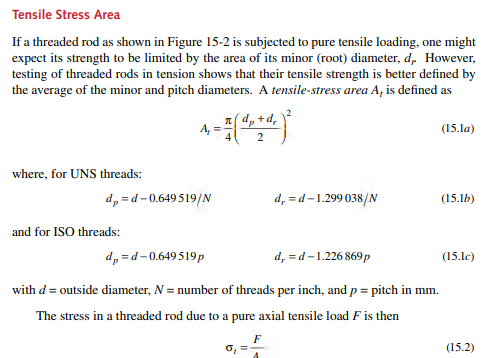

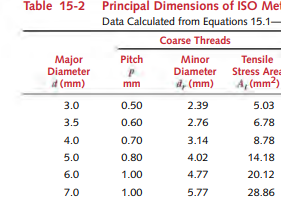

dia = 6;
pitch = 1;
diaPitch = dia - 0.649519*pitch;%mm 
diaRoot = dia - 1.226869*pitch ;%mm
AreaBoltTensile = pi/4*((diaPitch+diaRoot)/2)^2;%in mm^2
ABTMeters = AreaBoltTensile/1000000;%Converts to Meters
exampleGr5Tensile = 827370875;%Converted from psi
MaxTensileForFastener = exampleGr5Tensile*ABTMeters %newtons
SafetyFactorBoltTension = MaxTensileForFastener*2/TopCrossSecForce
SafetyFactorVoltShear = WidthCrossSecForce*12/MaxTensileForFastener

### Tear out 

[https://laminatedplastics.com/g-10.pdf](https://laminatedplastics.com/g-10.pdf) 

BoltDistanceFromEdge = 8/1000;%mm  realistic distance from edge
maxTearoutForce = BoltDistanceFromEdge*GaroliteThickness*garoliteStrength

### Flange Bonding

fr4BondStrength = 2200*psiTopPascal;
MinFlangeBondArea = DepthCrossSecForce/fr4BondStrength
DepthRestrictingBondArea = garoliteThickness * 80/1000
SideBondArea = 0.02* GaroliteThickness*2
bondMaxForce = fr4BondStrength * (DepthRestrictingBondArea + SideBondArea)

### Lid Deflection from 20g Loading

Packload = TopCrossSecForce ;
EneLidSegmentDepth = 6*EneModDepth + 0.082 -0.022;%
vmax = Packload * (EneLidSegmentDepth^4)/384/(garoliteFlexuralModulus)/((0.08*GaroliteThickness^3)/12)

## Euler-Johnson buckling limits

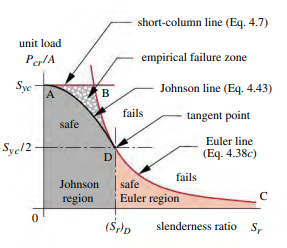

MomentOfInertiaSideWalls = 2*( (EneSegmentWidth/2+garoliteThickness/2)^2 * GaroliteThickness*(EneSegHeight+(2*GaroliteThickness))) + (garoliteThickness^3*SegmentCasingHeight/12)
% half width to get to walls + half of garolite thickness = centroid
% distance away, * area sidewall + garolite thickness^3(height) * segment height(width) 

MomentOfInertiaBottom = (garoliteThickness/2 + EneSegHeight/2)^2 * GaroliteThickness*EneSegmentWidth + (garoliteThickness^3*EneSegmentWidth/12)
MomentOfInertiaLid = (garoliteThickness/2 + EneSegHeight/2+(15/1000))^2 * GaroliteThickness*EneSegmentWidth + (garoliteThickness^3*EneSegmentWidth/12)

ixx = MomentOfInertiaLid + MomentOfInertiaBottom + MomentOfInertiaSideWalls
RadiusOfGyration = sqrt(ixx/DepthCrossSecArea)

SlendernessRatioCasing = EneSegmentDepth/RadiusOfGyration
SlendernessRatioForHalfStrength = pi*sqrt(2*garoliteFlexuralModulus/garoliteStrength)
MaxForceJohnson = DepthCrossSecArea *(garoliteStrength-(1/garoliteFlexuralModulus *(garoliteStrength*SlendernessRatioCasing/2/pi)^2))


### Passive Thermal Properties

SurfaceArea = EneSegmentDepth*EneSegmentWidth*2 + EneSegHeight*EneSegmentDepth*2;
heatFluxPerC = 1/garoliteThickness * 0.288 * SurfaceArea
